# Structured DIP with Hierachical NSOLTs

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: MATLAB R2021a

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2021, Shogo MURAMATSU, All rights reserved.

## Preparation

clear 
close all
support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## Bivariate lattice-structure oversampled filter banks 

As an example, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

## Hierachical decomposition for 2-D Grayscale image

Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation 

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


% Decimation factor (Strides)
decFactor = [2 2]; % [My Mx]

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 2% [Ps Pa] (Ps=Pa)

nChannels =      2     2


% Number of tree levels
nLevels = 2

nLevels = 2


% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancy = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))

redundancy = 1


% Polyphase Order
ppOrder = [1 1] *2

ppOrder =      2     2



% Lambda for soft-thresholding
%lambda4Ista = 1/8;

% Number of patchs per image
nSubImgs = 128;

% No DC-leakage
noDcLeakage = true

noDcLeakage = logical
   1


Setting of dictionary update step

% Number of iterations
nIters = 1; %5;

% Standard deviation of initial angles
stdInitAng = pi/6; 

% Patch size for training
szPatchTrn = [64 64]; % > [ (Ny+1)My (Nx+1)Mx ]

% Training options
opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    ...'InitialLearnRate',0.0100,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,... % Set zero since parameters are rotaion angles.
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',2,...16,...30,...
    'MiniBatchSize',2,...16,...128,...
    'Verbose',1,...
    'VerboseFrequency',2,...32,...50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','none',...'training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1

## Construction of layers

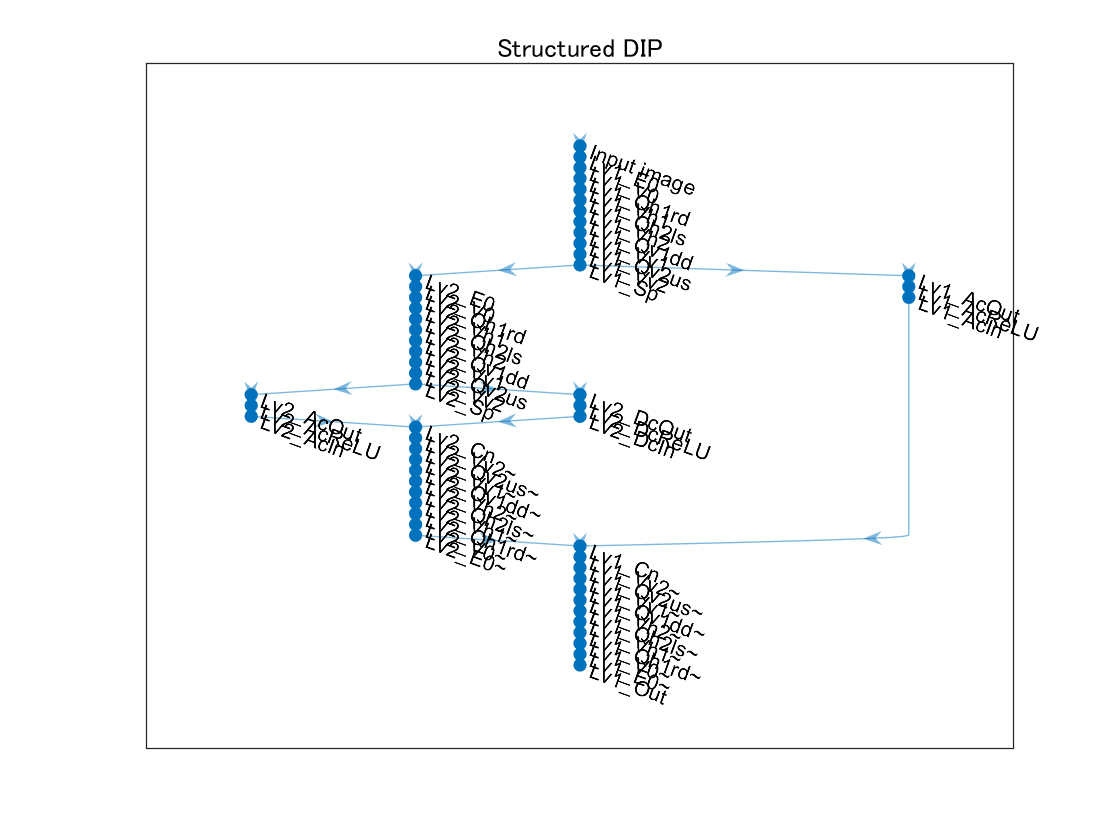

import saivdr.dcnn.*
sdiplgraph = fcn_createsdiplgraphs2d(...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage);

% Connect the NSOLT analyzer and synthesizer
strLv = sprintf('Lv%0d_',nLevels); 
sdiplgraph = sdiplgraph.addLayers(reluLayer('Name',[strLv 'DcReLU'])); % Activation function
sdiplgraph = sdiplgraph.connectLayers([strLv 'DcOut'],[strLv 'DcReLU']);
sdiplgraph = sdiplgraph.connectLayers([strLv 'DcReLU'],[strLv 'DcIn']);
for iLv = nLevels:-1:1
    strLv = sprintf('Lv%0d_',iLv); 
    sdiplgraph = sdiplgraph.addLayers(reluLayer('Name',[strLv 'AcReLU'])); % Activation function
    sdiplgraph = sdiplgraph.connectLayers([strLv 'AcOut'],[strLv 'AcReLU']);
    sdiplgraph = sdiplgraph.connectLayers([strLv 'AcReLU'],[strLv 'AcIn']);
end

% Replace input layer
sdiplgraph = sdiplgraph.replaceLayer(...
    'Lv1_In',...
    imageInputLayer(szPatchTrn,'Name','Input image','Normalization','none'));

figure(3)
plot(sdiplgraph)

title('Structured DIP')



% Construction of deep learning network.
sdipnet = dlnetwork(sdiplgraph);

% Initialize
nLearnables = height(sdipnet.Learnables);
for iLearnable = 1:nLearnables
    sdipnet.Learnables.Value(iLearnable) = ...
    cellfun(@(x) x+stdInitAng*randn(), ...
    sdipnet.Learnables.Value(iLearnable),'UniformOutput',false);
end

### Original image

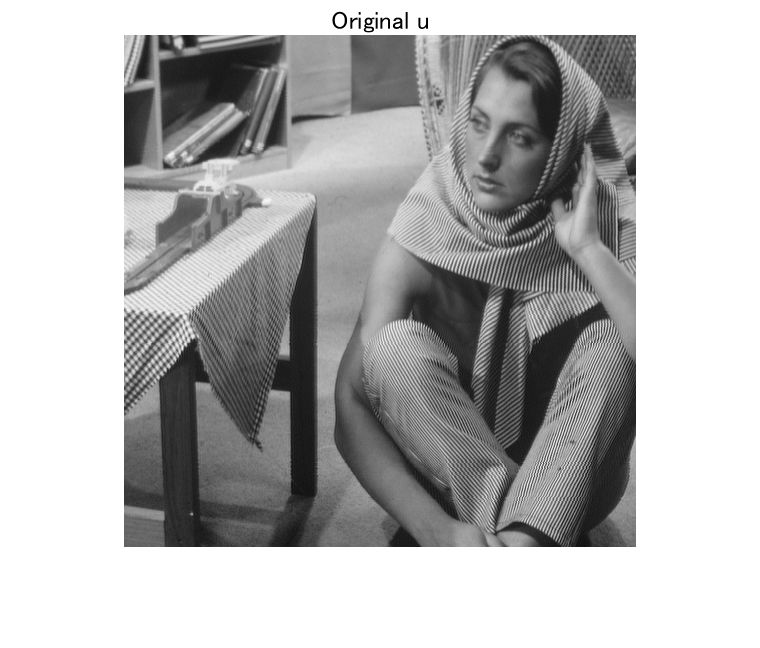

% Original image
%u = im2single(rgb2gray(imread('./data/baboon.png')));
u = im2single(imread('./data/barbara.png'));
figure(1)
imshow(u)
title('Original u')

imwrite(u,'./data/sdip_org.png')

### Observed image

Let us consider the single image super resolution problem of observation:

    
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


which originates  $\mathbf{u}$ and is contaminated by additive white Gaussian noise $\mathbf{w}$ and downscale measurement proces, where $\mathbf{P}$ is a linear process with identity operation

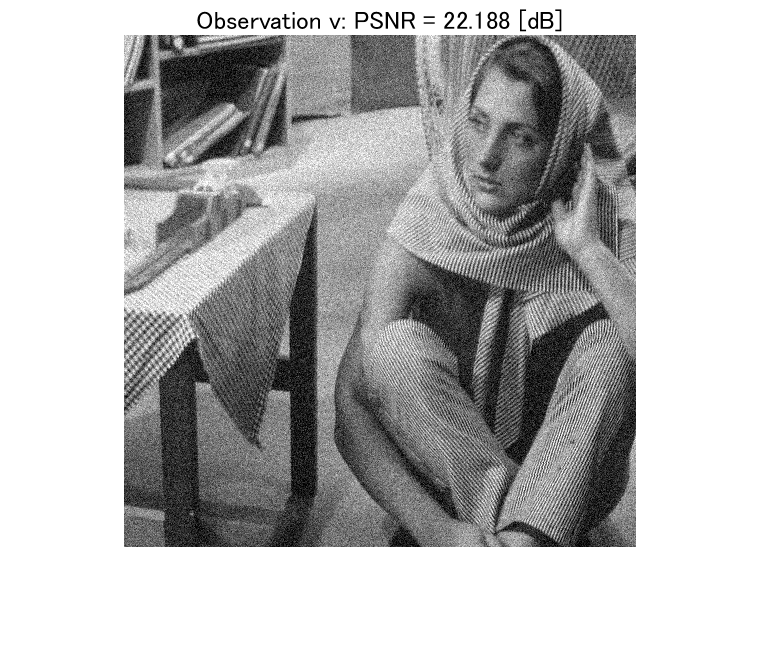

% Measurement process P
%sigmah = 2;
%h = fspecial('gaussian',9,sigmah);
%downsample2 = @(x,m) ipermute(downsample(permute(downsample(x,m),[2 1 3]),m),[2 1 3]);
%linproc = @(x) downsample2(imfilter(x,h,'conv','circ'),2);
linproc = @(x) x;
%H = fftn(h,2.^nextpow2([size(u,1) size(u,2)]));
%beta = max(abs(H(:)).^2); % λmax(PP.')
beta = 1;

% Observation
sigmaw = 20/255;
v = imnoise(linproc(u),'gaussian',0,sigmaw^2);
figure(2)
imshow(v)
title(['Observation v: PSNR = ' num2str(psnr(u,v)) ' [dB]']);

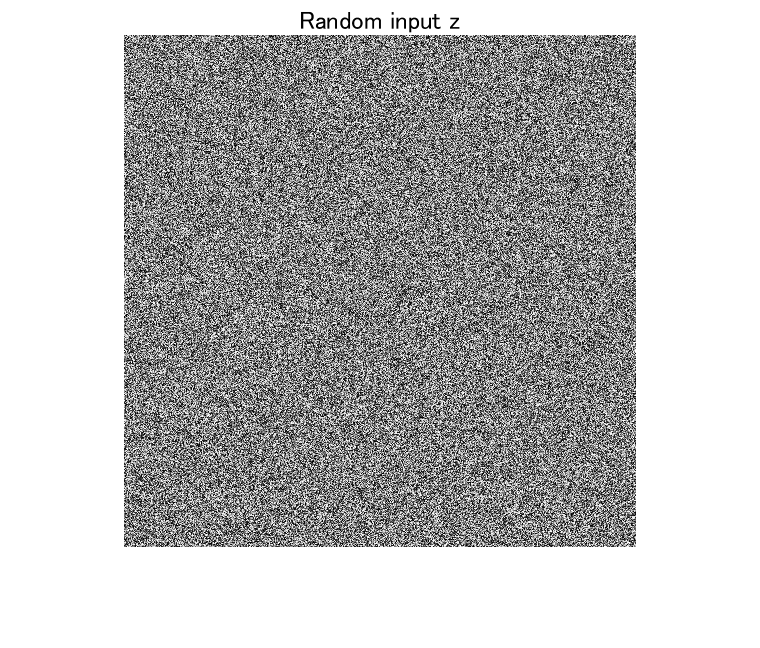



imgufile = './data/sdip_obs.png';
imwrite(v,imgufile);

% Random input
z = rand(size(u),'like',u);
figure(3)
imshow(z)
title('Random input z');

imgzfile = './data/sdip_rnd.png';
imwrite(z,imgzfile);

Randomly extracting patches from the target image

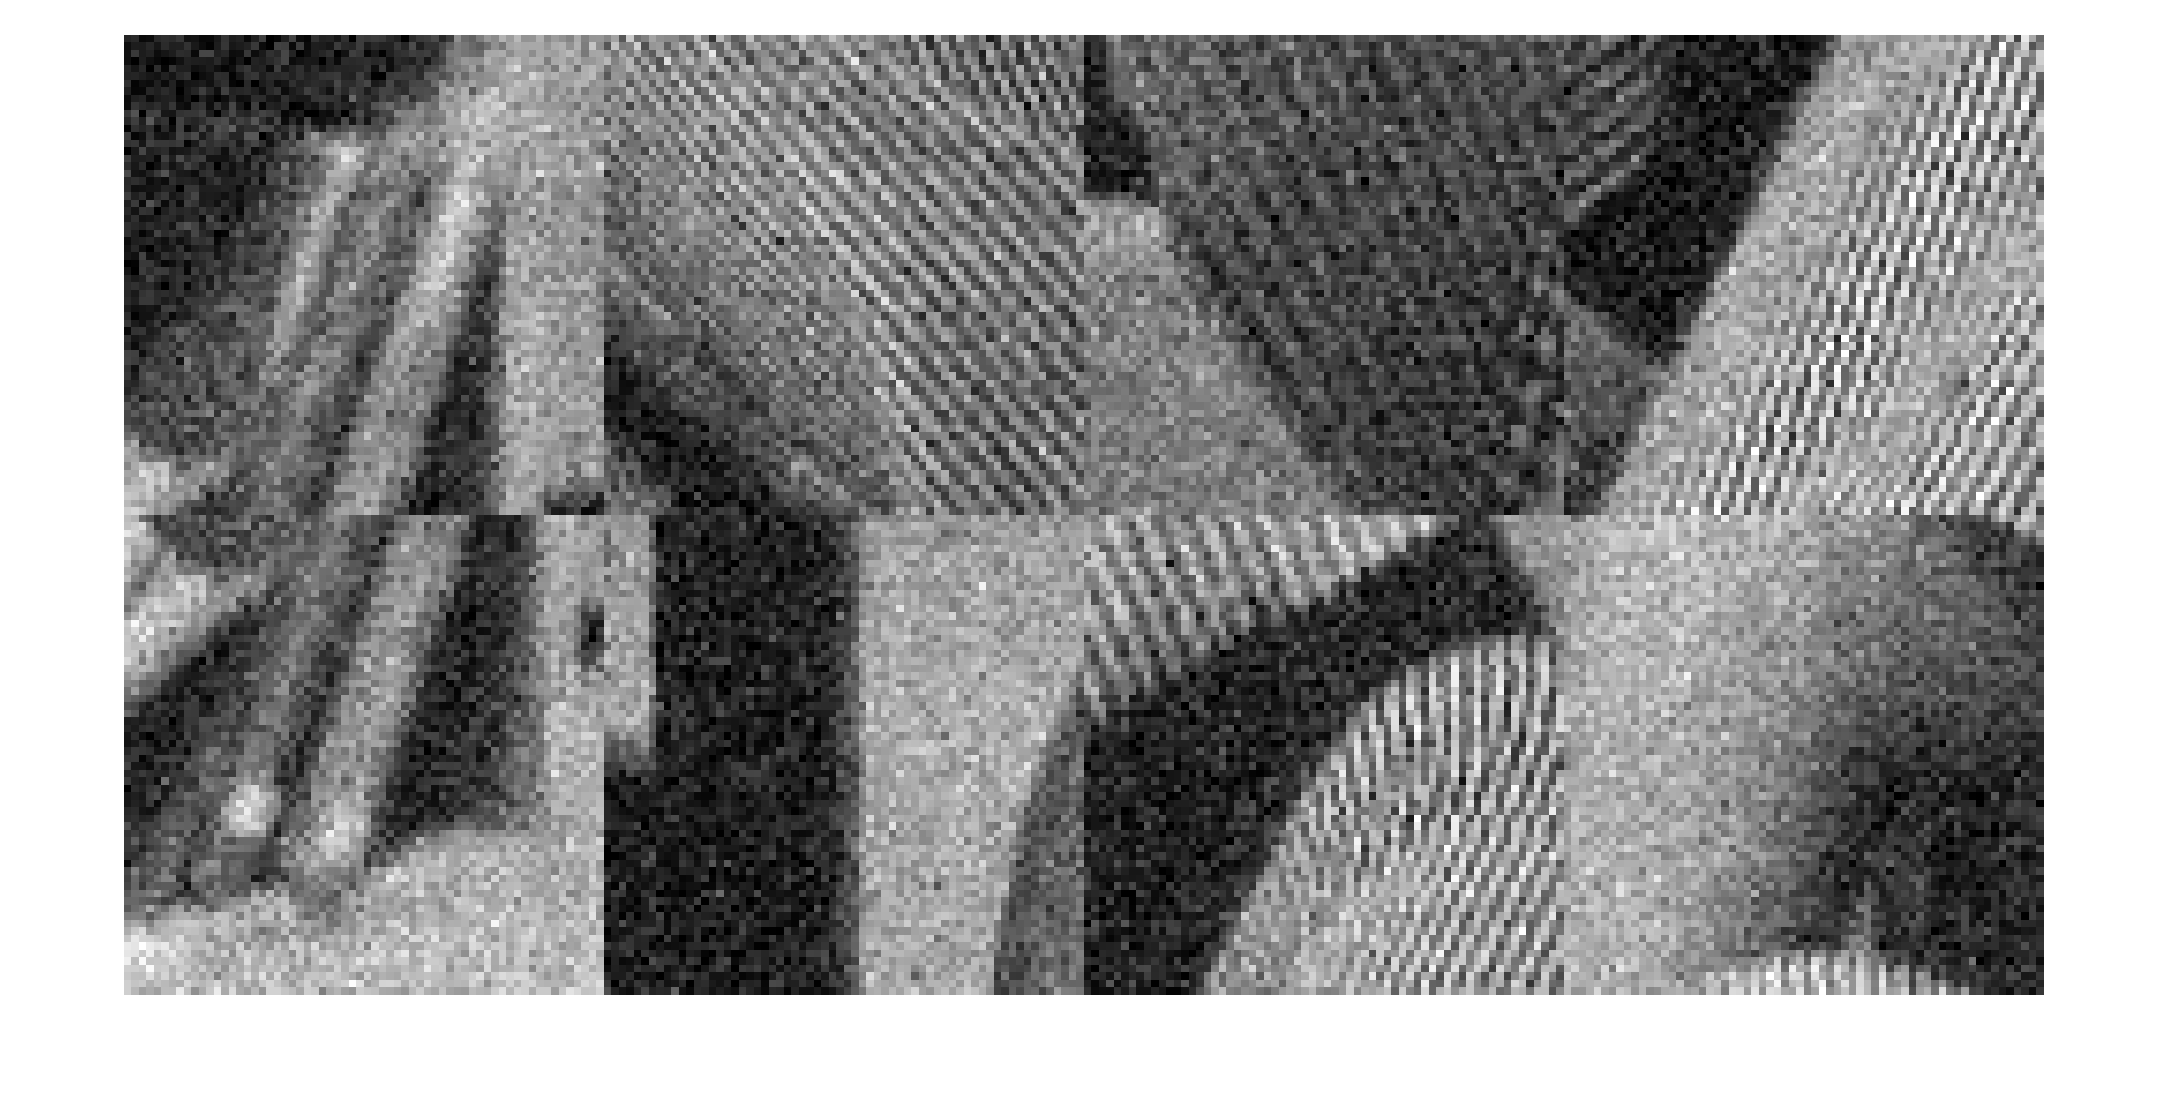

% Random input
imdsz = imageDatastore(imgzfile,"ReadFcn",@(x) im2single(imread(x)));
% Observation 
imdsu = imageDatastore(imgufile,"ReadFcn",@(x) im2single(imread(x)));

% Random input training 
patchds = randomPatchExtractionDatastore(imdsz,imdsu,szPatchTrn,'PatchesPerImage',nSubImgs);
figure(4)
minibatch = preview(patchds);
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);

### Structured DIP

#### Problem setting:

    
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-d(\mathbf{D}_{\theta_s}\phi_{\theta_f}(\mathbf{T}_{\theta_a}\mathbf{z}_n))\|_2^2,$$$


where $\mathbf{T}_{\theta}$  and $\mathbf{D}_{\theta}$ are an analysis and synthesis convolutional dictionary with the design parameters.

## Training


% Replace output layer
trainlgraph = sdiplgraph.replaceLayer(...
    'Lv1_Out',...
    regressionLayer('Name','regression output'));

% Analyze network 
analyzeNetwork(trainlgraph)

% Training
sdipdagnet = trainNetwork(patchds,trainlgraph,opts);

単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：０３　｜　　　　　　　　２０．２２　｜　　　　　２０４．３　｜　　０．０１００　｜
｜　　　　　　１　｜　　　　２　｜　　　　　００：００：０６　｜　　　　　　　　１８．９７　｜　　　　　１８０．０　｜　　０．０１００　｜
｜　　　　　　１　｜　　　　４　｜　　　　　００：００：１１　｜　　　　　　　　２０．３３　｜　　　　　２０６．７　｜　　０．０１００　｜
｜　　　　　　１　｜　　　　６　｜　　　　　００：００：１６　｜　　　　　　　　２０．６１　｜　　　　　２１２．３　｜　　０．０１００　｜
｜　　　　　　１　｜　　　　８　｜　　　　　００：００：２１　｜　　　　　　　　２１．６１　｜　　　　　２３３．５　｜　　０．０１００　｜
｜　　　　　　１　｜　　　１０　｜　　　　　００：００：２６　｜　　　　　　　　２０．６６　｜　　　　　２１３．４　｜　　０．０１００　｜
｜　　　　　　１　｜　　　１２　｜　　　　　００：００：３１　｜　　　　　　　　２０．９９　｜　　　　　２２０．４　｜　　０．０１００　｜
｜　　　　　　１　｜　　　１４　｜　　　　　００：００：３６　｜　　　　　　　　１９．３５　｜　　　　　１８７．２　｜　　０．０１００　｜
｜　　　　　　１　｜　　　１６　｜　　　　　００：００：４１　｜　　　　　　　　２０．４１　｜　　　　　２０８．２　｜　　０．０１００　｜
｜　　　　　　１　｜　　　１８　｜　　　　　００：００：４７　｜　　　　　　　　２０．２０　｜　　　　　２０４．１　｜　　０．０１００　｜
｜　　　　　


%profile off
%profile viewer

## Restoration

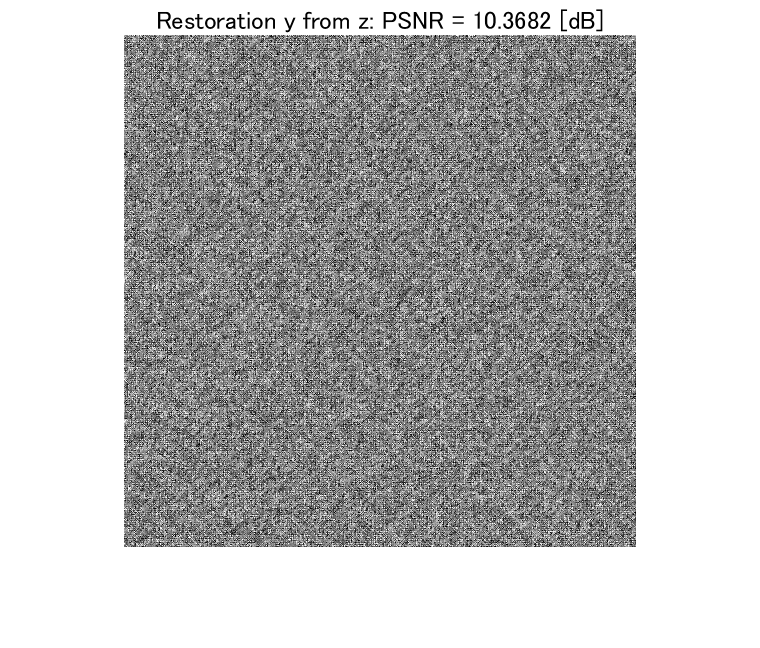

sdiplgraph = layerGraph(sdipdagnet); 
sdiplgraph = sdiplgraph.replaceLayer('regression output',...
        saivdr.dcnn.nsoltIdentityLayer('Name','Lv1_Out'));
sdiplgraph = sdiplgraph.replaceLayer('Input image',...
        imageInputLayer(size(u),'Name','Input image','Normalization','none'));

% Random input
dlz =dlarray(z,'SSC');
dly = sdipnet.predict(dlz);
y = extractdata(dly);

% Observation input
dlv =dlarray(v,'SSC');
dlr = sdipnet.predict(dlv);
r = extractdata(dlr);

figure(5)
imshow(y)
title(['Restoration y from z: PSNR = ' num2str(psnr(u,y)) ' [dB]']);

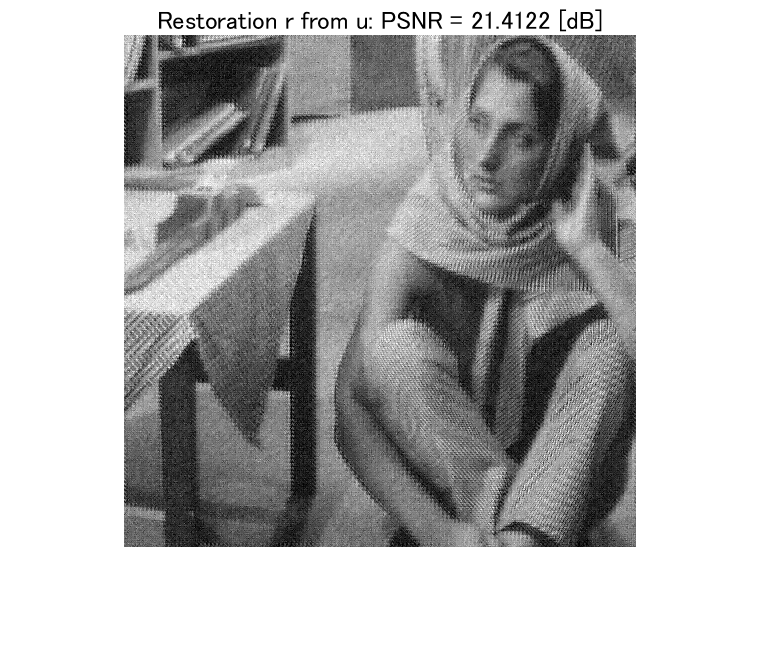

imwrite(y,'./data/sdip_rsy.png')

figure(6)
imshow(r)
title(['Restoration r from u: PSNR = ' num2str(psnr(u,r)) ' [dB]']);

imwrite(r,'./data/sdip_rsr.png')

### Save the designed network

save(sprintf('./data/sdipnetwork_%s',datetime('now','Format','yyyyMMddhhmmssSSS')),'sdiplgraph','u','v','z','r')

© Copyright, Shogo MURAMATSU, All rights reserved.